Function

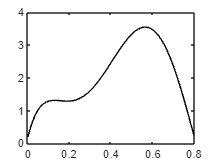

f=@(x) 400.*x.^5 - 900.*x.^4 + 675.*x.^3 - 200.*x.^2 + 25.*x + 0.2;

% f=@(x) 400.*x.^5 - 900.*x.^4 + 675.*x.^3 - 200.*x.^2 + 25.*x + 0.2;

xx = linspace(0, 0.8);
yy = f(xx);
plot(xx,yy,'k-')

To integrate function from 0 to 0.8

a = 0;
b = 0.8;

p = [400 -900 675 -200 25 0.2];
q = polyint(p);

Itrue = diff(polyval(q, [a b]))

Itrue = 1.6405

Plot original function along with simpson 1/3 rule with ns calculated from adaptive quadrature

[I_quadapt,xpts] = quadadaptwithpoint(f,a,b);

I_quadapt

I_quadapt = 1.6405


ypts = f(xpts);

[xpts ypts]

ans =          0    0.0063    0.0094    0.0125    0.0250    0.0312    0.0344    0.0375    0.0500    0.0563    0.0594    0.0625    0.0750    0.0813    0.0844    0.0875    0.1000    0.1063    0.1094    0.1125    0.1250    0.1313    0.1344    0.1375    0.1500    0.1563    0.1594    0.1625    0.1750    0.1813    0.1844    0.1875    0.2000    0.2063    0.2094    0.2125    0.2250    0.2313    0.2344    0.2375    0.2500    0.2625    0.2688    0.2750    0.3000    0.3125    0.3188    0.3250    0.3500    0.3625



ns = (length(xpts)-1)/2

ns = 46

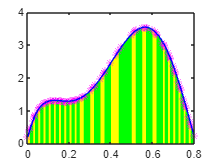


figure
color = ['g','y'];
for i = 1:ns
    il = 2*(i-1)+1;
    ir = 2*i+1;
    newx = xpts(il:ir);
    newy = ypts(il:ir);
    p2 = polyfit(newx,newy,2);
    xx2 = linspace(xpts(il),xpts(ir));
    yy2 = polyval(p2,xx2);

    area(xx2,yy2,'FaceColor',color(mod(i,2)+1),'EdgeColor','black','LineStyle','-')

    hold on
    plot(xpts(il:ir),ypts(il:ir),'m*')
end
plot(xx,yy,'b-')